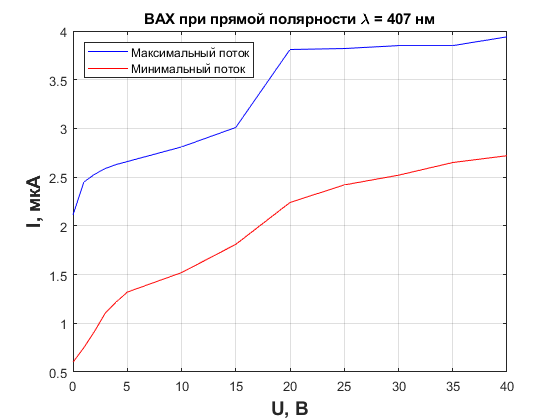

cla reset;
U_1 =  [   0    1    2    3    4    5   10   15   20   25   30   35   40];
I1_1 = [2.11 2.45 2.53 2.59 2.63 2.66 2.81 3.01 3.81 3.82 3.85 3.85 3.94];
I2_1 = [ 0.6 0.75 0.92 1.11 1.22 1.32 1.52 1.81 2.24 2.42 2.52 2.65 2.72];
plot(U_1, I1_1, 'Color', 'blue');
hold on;
plot(U_1, I2_1, 'Color', 'red');
grid on;
title('ВАХ при прямой полярности {\lambda} = 407 нм');
ylabel('I, мкА','FontSize',14,'FontWeight','bold');
xlabel('U, В','FontSize',14,'FontWeight','bold');
legend('Максимальный поток', 'Минимальный поток','Location','northwest');
% saveas(gcf,'k21_plot_table_1.png');
hold off;

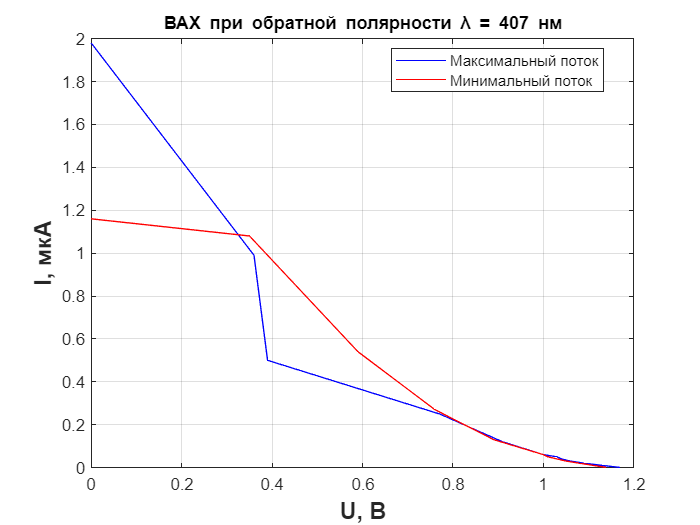

U1_2 = [   0 0.36 0.39 0.77 0.91    1 1.03 1.04 1.06 1.09 1.13 1.17];
I1_2 = [1.98 0.99  0.5 0.25 0.12 0.06 0.05 0.04 0.03 0.02 0.01    0];
U2_2 = [   0 0.35 0.59 0.76 0.89    1 1.01 1.03 1.05 1.08 1.11 1.14];
I2_2 = [1.16 1.08 0.54 0.27 0.13 0.06 0.05 0.04 0.03 0.02 0.01    0];
plot(U1_2, I1_2, 'Color', 'blue');
hold on;
plot(U2_2, I2_2, 'Color', 'red');
grid on;
title('ВАХ при обратной полярности {\lambda} = 407 нм');
ylabel('I, мкА','FontSize',14,'FontWeight','bold');
xlabel('U, В','FontSize',14,'FontWeight','bold');
legend('Максимальный поток', 'Минимальный поток','Location','best');
% saveas(gcf,'k21_plot_table_2.png');
hold off;

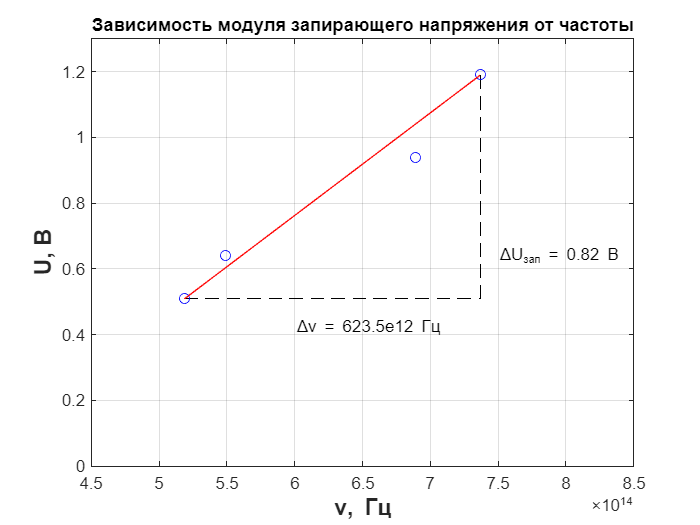

Nu =  [ 737  689  549  519] * 1e12;
U_3 = [1.19 0.94 0.64 0.51];
x1 = [519 737] *1e12; y1 = [0.51 0.51]; x2 = [737 737] *1e12; y2 = [0.51 1.19];
X = [519 737] *1e12; Y = [0.51 1.19];
dU_3 = (U_3(1) + U_3(2) + U_3(3) +  U_3(4))/4;
dNu = (Nu(1) + Nu(2) + Nu(3) +  Nu(4))/4;
plot(x1, y1, '--', 'Color','black');
hold on;
plot(x2, y2, '--', 'Color','black');
plot(Nu, U_3, 'o', "Color", "blue");
plot(X, Y, 'Color', 'red');
ylim([0 1.3]);
xlim([4.5e14 8.5e14]);
ylabel('U, В','FontSize',14,'FontWeight','bold');
xlabel('{\nu}, Гц','FontSize',14,'FontWeight','bold');
grid on;
text(7.5e14, 0.64,'{\Delta}U_{зап} = 0.82 В', 'Color','black');
text(6e14, 0.42,'{\Delta}{\nu} = 623.5e12 Гц', 'Color','black');
title('Зависимость модуля запирающего напряжения от частоты');

% saveas(gcf,'k21_plot_table_3.png');
e = 1.6e-19;
h = 6.6262e-34;
c = 3e8;
S_lamda = 450;
lamda = 407e-9;
I0 = [3.94 1.94];
F = I0/S_lamda

F =     0.0088    0.0043


n = I0/e

n = 	1.0e+19 *

    2.4625    1.2125


h_e = e * dU_3 / dNu

h_e = 2.1043e-34

Eps = abs(h - h_e)/h * 100

Eps = 68.2435

lamda = 546e-9;
E = (h*c)/lamda

E = 3.6408e-19

E_e = E/e

E_e = 2.2755